clear;clc;

## 读取数据

load("PointOctahedron.mat")
P_bound1 = top_face_transformed(10,:);
P_bound2 = bottom_face_transformed(20,:);
planes = planes';




PAB = [-0.176,-0.06,0.6]';
% P_bound1 = [-0.142,0.47,0.061]*2;
% P_bound2 = [0.57,-0.48,0.138];
phi = pi./6;
phi = pi./2 - phi;
shenglunum = 5;
a = 0.015*ones(1,2*shenglunum);
distanceThreshold = 0.2;


[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,0.2);





## 计算 AB面

% 加 输出   计算 和判断 偏移
Ti = ShengDaoGaoDu(shenglunum);

[PointTable_A_off8,PointTable_B_off8,XieMianPianYi] = Calculate_rectangle_from_vertex8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

PointTable_A_off8 =     0.2854    0.0460   -0.1801   -0.3420   -0.3748   -0.0850    0.1540    0.3803    0.5416    0.5738
   -0.3349   -0.2160   -0.0783    0.0413    0.1022    0.0209   -0.0979   -0.2357   -0.3552   -0.4159
   -0.0295   -0.2994   -0.3231   -0.1480    0.2213    1.1177    1.3863    1.4109    1.2338    0.8628


PointTable_B_off8 =     0.5745    0.5428    0.3803    0.1543   -0.0848   -0.3753   -0.3428   -0.1801    0.0483    0.2867
   -0.0077    0.3456    0.5554    0.6037    0.4296   -0.3088   -0.6602   -0.8694   -0.9116   -0.7394
    0.1591    0.0259    0.0435    0.1746    0.4117    0.9303    1.0622    1.0442    0.9089    0.6730


XieMianPianYi =     0.0150    0.0150         0    0.0149    0.0149    0.0150    0.0150         0    0.0150    0.0150


## 验证

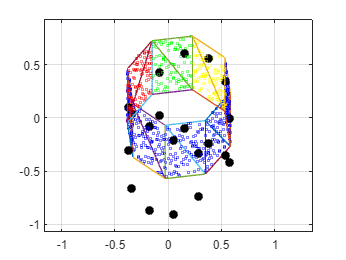

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(:,1),side_faces_transformed1(:,2),side_faces_transformed1(:,3),5,'yellow')
scatter3(side_faces_transformed2(:,1),side_faces_transformed2(:,2),side_faces_transformed2(:,3),5,'green')
scatter3(side_faces_transformed3(:,1),side_faces_transformed3(:,2),side_faces_transformed3(:,3),5,'red')
scatter3(side_faces_transformed4(:,1),side_faces_transformed4(:,2),side_faces_transformed4(:,3),5,'blue')
scatter3(side_faces_transformed5(:,1),side_faces_transformed5(:,2),side_faces_transformed5(:,3),5,'blue')
scatter3(side_faces_transformed6(:,1),side_faces_transformed6(:,2),side_faces_transformed6(:,3),5,'blue')
scatter3(side_faces_transformed7(:,1),side_faces_transformed7(:,2),side_faces_transformed7(:,3),5,'blue')
scatter3(side_faces_transformed8(:,1),side_faces_transformed8(:,2),side_faces_transformed8(:,3),5,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end

scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')

## 构建复测数据

% 构建测点输入
PointIn = [];
for i = 1:shenglunum
    temp = [PointTable_A_off8(:,i),PointTable_A_off8(:,end+1-i)];
    PointIn = [PointIn,temp];
end

% 计算参数（用于输入）
[PlaneParaOut,TrianglePoints4,~,~] = planefit4(side_faces_transformed1',side_faces_transformed3',side_faces_transformed5',side_faces_transformed7',P_bound1,P_bound2,distanceThreshold);
[Pin,Pout,UPP,b,h,~,Tao,~] = Calculate_rectangle_from_vertex(TrianglePoints4);




## 计算距离

Distance = zeros(1,shenglunum);
for i = 1:shenglunum
    shengdao = PointIn(:,[2*i-1,2*i]);
    Distance(i) = norm(PointIn(:,2*i-1)-PointIn(:,2*i));
end

## 计算声道角度

% % 计算水平方向向量
% dir1 = UPP - Pin;
% dir2 = Tao;
% dir3 = cross(dir1,dir2);
% 
% % 水平方向第二个点
% Pright = Pin+dir3;
% 
% % 向水平方向投影并计算夹角
theta = zeros(1,shenglunum);
% % 水平面参数
% a = PlaneParaOut(1,4);
% b = PlaneParaOut(2,4);
% c = PlaneParaOut(3,4);
% d = PlaneParaOut(4,4);



for i = 1:shenglunum
    shengdao1 = PointIn(:,2*i-1);
    shengdao2 = PointIn(:,2*i);

    SPXL = shengdao2 - shengdao1;
    theta(i) = acos(dot(Tao, SPXL) / (norm(Tao) * norm(SPXL)));  
end
theta = pi- theta;
rad2deg(theta)

ans =    30.2713   30.2713   30.2713   30.2713   30.2713


## 计算LT


DistanceYC = zeros(1,shenglunum);
for i = 1:shenglunum
    shengdao1 = PointIn(:,2*i-1);
    shengdao2 = PointIn(:,2*i);
    dir_vec = shengdao2 - shengdao1;

    % 计算方向向量
    a = PlaneParaOut8(1,1);
    b = PlaneParaOut8(2,1);
    c = PlaneParaOut8(3,1);
    d = PlaneParaOut8(4,1);
    % 将直线方程代入平面方程，求解参数 t
    xN5 = shengdao1(1);
    yN5 = shengdao1(2);
    zN5 = shengdao1(3);
    t = -(a*xN5 + b*yN5 + c*zN5 + d) / (a*dir_vec(1) + b*dir_vec(2) + c*dir_vec(3));
    % 计算交点
    x_intersect1 = xN5 + t * dir_vec(1);
    y_intersect1 = yN5 + t * dir_vec(2);
    z_intersect1 = zN5 + t * dir_vec(3);
    temp3 = [x_intersect1;y_intersect1;z_intersect1];


    % 计算方向向量
    a = PlaneParaOut8(1,5);
    b = PlaneParaOut8(2,5);
    c = PlaneParaOut8(3,5);
    d = PlaneParaOut8(4,5);
    % 将直线方程代入平面方程，求解参数 t
    xN5 = shengdao1(1);
    yN5 = shengdao1(2);
    zN5 = shengdao1(3);
    t = -(a*xN5 + b*yN5 + c*zN5 + d) / (a*dir_vec(1) + b*dir_vec(2) + c*dir_vec(3));
    % 计算交点
    x_intersect2 = xN5 + t * dir_vec(1);
    y_intersect2 = yN5 + t * dir_vec(2);
    z_intersect2 = zN5 + t * dir_vec(3);
    temp4 = [x_intersect2;y_intersect2;z_intersect2];

    DistanceYC(i) = norm(temp4-temp3);

end

LTPY = Distance - DistanceYC;


## 相对高度计算

TiC = zeros(1,2*shenglunum);
for i = 1:2*shenglunum
    shengdao = PointIn(:,i);

    a = PlaneParaOut8(1,3);
    b = PlaneParaOut8(2,3);
    c = PlaneParaOut8(3,3);
    x = Pin(1);
    y = Pin(2);
    z = Pin(3);
    d =  -(a*x+b*y+c*z);
    xN5 = shengdao(1);
    yN5 = shengdao(2);
    zN5 = shengdao(3);
    dir_vec = [a,b,c];

    % 计算交点
    t = -(a*xN5 + b*yN5 + c*zN5 + d) / (a*dir_vec(1) + b*dir_vec(2) + c*dir_vec(3));
    x_intersect3 = xN5 + t * dir_vec(1);
    y_intersect3 = yN5 + t * dir_vec(2);
    z_intersect3 = zN5 + t * dir_vec(3);
    temp5 = [x_intersect3;y_intersect3;z_intersect3];
    
    % 计算高度
    TiC(i) = 2*norm(temp5 - shengdao)/h;

end

if mod(shenglunum,2)==1 %奇数
    temp6 = floor(shenglunum./2);
    TiC(1:2*temp6) = -TiC(1:2*temp6);
else %偶数
    temp6 = shenglunum./2;
     TiC(1:2*temp6) = -TiC(1:2*temp6);
end

## 计算权重

k1 = 0.5;
k2 = 0.6;
k3 = 0;
k4 = 0.15;

gk1 = [1.570796,0.392699,0.19635,0.122718,0.085903];
gk2 = [1.513365,0.360325,0.174351,0.106311,0.072959];
gk3 = [2,2/3,2/5,2/7,2/9];
gk4 = [1.838286,0.556753,0.315143,0.215852,0.162469];

gk = gk4;
k = k4;


TiYiCe = TiC(1:2:2*shenglunum);


if mod(shenglunum,2)==1 %奇数
    temp6 = floor(shenglunum./2);
    TiYiCe(temp6+1) = 0;
end

t_k = zeros(shenglunum-1,1);
w = zeros(shenglunum,1);
f = zeros(shenglunum,1);

    for i=1:shenglunum  
        count_tk = 1;
        for m=1:shenglunum
            if(m~=i)
            t_k(count_tk) =  TiYiCe(m);
            count_tk = count_tk + 1;
            end
        end  

        for j=1:(shenglunum+1)/2
             f(j) = -sum(prod(nchoosek(t_k,(shenglunum+1-2*j)),2)); 
             w(i) = w(i) + gk(j)*f(j);
        end

        mul = 1;
        for m=1:shenglunum
            if(m ~= i)
                mul = mul*(TiYiCe(i) - TiYiCe(m));
            end
        end
        w(i)=w(i)/((1-TiYiCe(i)*TiYiCe(i))^k * mul);    
    end

    Wquanzhong = abs(repelem(w,2))

Wquanzhong =     0.2456
    0.2456
    0.4711
    0.4711
    0.5562
    0.5562
    0.4751
    0.4751
    0.2403
    0.2403
